# Изучение движения звёзд

close all
clear variables

## Импорт данных

spectra = importdata('spectra.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');
starNames = importdata('star_names.csv');

## Константы

lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/с

## Определение диапазона длин волн

nObs = size(spectra, 1);
nStar = size(spectra, 2);
lambdaEnd = lambdaStart + (nObs - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

## Расчёт скорости удаления звезды от Земли

s = spectra;
[sHa, idx] = min(s);
lambdaHa = lambda(idx);

z = (lambdaHa / lambdaPr) - 1;
speed = z * speedOfLight;
movaway = starNames(speed > 0);

## Построение графика

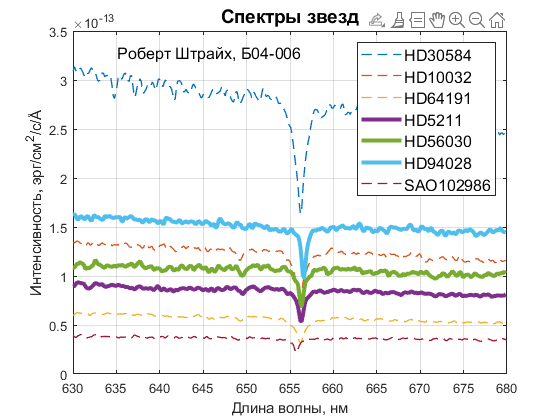

fg1 = figure;
p = plot(lambda, s, '--', 'LineWidth', 1);
for i = 1 : 1 : nStar
     if speed(i) > 0
       p(i).LineWidth = 3;
       p(i).LineStyle = '-';
     end
end
set(fg1, 'visible', 'on');
xlabel('Длина волны, нм');
ylabel(['Интенсивность, эрг/см^2/c/', char(197)]);
title('Спектры звезд', 'FontSize', 14);
legend(starNames, 'FontSize', 12);
grid on;
text(lambdaStart + 5, max(s(1)) + 2*10^-14, 'Роберт Штрайх, Б04-006', 'FontSize', 12);

## Сохранение графика

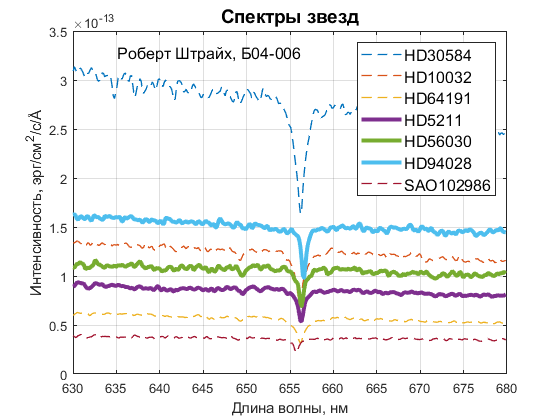

saveas(fg1, 'spectra.png');